# Dinamica Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale

clear
clc
digits(4)

## Definizione delle variabili simboliche

syms t; % tempo
syms T; % Energia cinetica del sistema
syms U; % Energia potenziale del sistema
syms alpha; % Angolo di offset (inclinazione utente) che sposta in avanti il baricentro
syms beta; % Angolo baricentro asta

syms q_1 q_1_p q_2 q_2_p; % Coordinate libere
syms phi(t); % Posizione carrello/r
vel = diff(phi, t); % Velocità carello / r
syms theta(t); % Angolo inclinazione
vel_ang = diff(theta, t); % Vel angolare
syms C_m; % Forza esterna

## Definizione masse e gravità

% Massa singola ruota
m_r = sym('3');
% Massa asta
m_a = sym('3.5');
% Massa uomo (da far variare poi)
m_c = sym('70');

% Massa carello(base) + batterie: si suppongo le batterie all'interno di
% questa massa
m_b = sym('20');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante di accelerazione di gravità
g = sym('9.80665');

## Definizione delle altezze

Dimensioni espresse tutte in [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Altezza uomo
h_c = sym('1.70');

% Raggio ruota
r = sym('0.22');

## Definizione inerzie

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo
J_c = (1732353*h_c + 619298*2.20462*m_c - 277625773)*10e-7;

% Inerzia della singola ruota
J_r = sym('0.1452');

## Definizione delle costanti geometriche $\alpha \;e\;\beta \;$

Si definiscono i parametri geometrici d'interesse come in immagine, la quale si trova in una condizione di $\theta =0\ldotp$

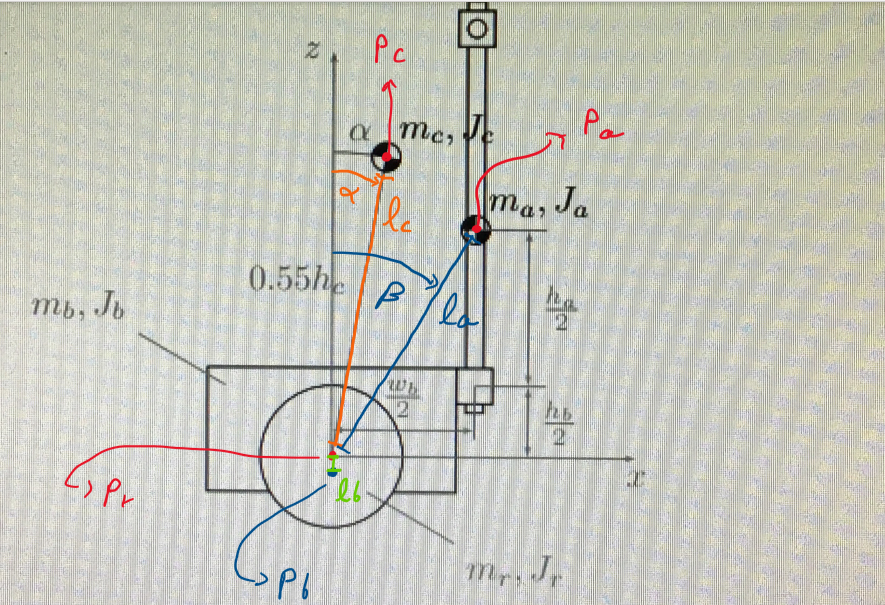

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;

l_c = 0.55 * h_c

$$l\_c = 0.935$$

l_b = 0.1

l_b = 0.1000

l_a = sqrt((temp_1)^2 + (temp_2)^2)

$$l\_a = 0.8382$$


alpha = 0

alpha = 0

beta = atan(temp_2/temp_1)

$$beta = 0.3029$$

## Calcolo componenti dinamiche e potenziali per ogni corpo rigido del sistema

Nello specifico abbiamo considerato il sistema composto da:

- Asta ($P_a$)

- Utente a bordo dello chassis ($P_c$)

- Chassis (o base) ($P_b$)

- Ruota ($P_r$) che poi sarà considerata con un contributo doppio, essendo 2 le ruote del sistema

Per ognuno di questi corpi rigidi siamo andati a calcolare:

- Coordinate spaziali nel sistema di riferimento XZ, con l'aggiunta delle coordinate angolari $$\rightarrow$$ vettore 3 x 1

- Vettore delle velocità $$\rightarrow$$ vettore 3 x 1

- Matrice delle masse $$\rightarrow$$ matrice 3 x 3

- Energia cinetica dello specifico corpo rigido $$\rightarrow$$ $T=\frac{1}{2\;}\bullet V^T \bullet M\bullet V$

- Energia potenziale dello specifico corpo rigido$$\rightarrow$$ $U$

- Lagrangiana dello specifico corpo rigido $$\rightarrow$$ $L=T-U$

### Asta $P_a$

P_a = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta); theta]

$$P\_a(t) = \left(\begin{array}{c} 0.8382\,\sin\left(\theta \left(t\right)+0.3029\right)+0.22\,\varphi \left(t\right)\\ 0.8382\,\cos\left(\theta \left(t\right)+0.3029\right)\\ \theta \left(t\right) \end{array}\right)$$

V_a = diff(P_a, t)

$$V\_a(t) = \left(\begin{array}{c} 0.8382\,\cos\left(\theta \left(t\right)+0.3029\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -0.8382\,\sin\left(\theta \left(t\right)+0.3029\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_a = [m_a,0,0; 0,m_a,0; 0,0,J_a] % Matrice delle masse/inerzie

$$M\_a = \left(\begin{array}{ccc} 3.5 & 0 & 0\\ 0 & 3.5 & 0\\ 0 & 0 & 0.1669 \end{array}\right)$$

T_a = 1/2 * transpose(V_a) * M_a * V_a;
U_a = m_a * g * l_a * cos(theta+beta);
L_a = T_a - U_a

$$L\_a(t) = \begin{array}{l} 0.08345\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-28.77\,\sigma_{1}+\left(1.467\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+0.385\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(0.8382\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)+1.229\,{\sin\left(\theta \left(t\right)+0.3029\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \left(t\right)+0.3029\right) \end{array}$$

### Utente  $P_c$

P_c = [phi*r+l_c*sin(theta+alpha); l_c*cos(theta+alpha); theta + alpha]

$$P\_c(t) = \left(\begin{array}{c} 0.935\,\sin\left(\theta \left(t\right)\right)+0.22\,\varphi \left(t\right)\\ 0.935\,\cos\left(\theta \left(t\right)\right)\\ \theta \left(t\right) \end{array}\right)$$

V_c = diff(P_c,t)

$$V\_c(t) = \left(\begin{array}{c} 0.935\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -0.935\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_c = [m_c,0,0; 0,m_c,0; 0,0,J_c]

$$M\_c = \left(\begin{array}{ccc} 70 & 0 & 0\\ 0 & 70 & 0\\ 0 & 0 & -179.1 \end{array}\right)$$

T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c * cos(alpha+theta);
L_c = T_c - U_c

$$L\_c(t) = 30.6\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-89.55\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-641.8\,\cos\left(\theta \left(t\right)\right)+\left(32.73\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+7.7\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(0.935\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)$$

### Chassis (o base)  $P_b$

P_b = [phi*r+l_b*sin(pi+theta); l_b*cos(pi+theta); pi+theta]

$$P\_b(t) = \left(\begin{array}{c} 0.22\,\varphi \left(t\right)-\frac{\sin\left(\theta \left(t\right)\right)}{10}\\ -\frac{\cos\left(\theta \left(t\right)\right)}{10}\\ \pi +\theta \left(t\right) \end{array}\right)$$

V_b = diff(P_b,t)

$$V\_b(t) = \left(\begin{array}{c} 0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{10}\\ \frac{\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{10}\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_b = [m_b,0,0; 0,m_b,0; 0,0,J_b]

$$M\_b = \left(\begin{array}{ccc} 20 & 0 & 0\\ 0 & 20 & 0\\ 0 & 0 & 0.6667 \end{array}\right)$$

T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b * cos(pi+theta);
L_b = T_b - U_b

$$L\_b(t) = \begin{array}{l} 19.61\,\cos\left(\theta \left(t\right)\right)+0.3333\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{10}+\left(\sigma_{1}-2.2\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(\frac{\sigma_{1}}{10}-0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Ruota $P_r$

P_r = [phi*r; 0; phi]

$$P\_r(t) = \left(\begin{array}{c} 0.22\,\varphi \left(t\right)\\ 0\\ \varphi \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t)

$$V\_r(t) = \left(\begin{array}{c} 0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0\\ \frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

M_r = [m_r,0,0; 0,m_r,0; 0,0,J_r]

$$M\_r = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 3 & 0\\ 0 & 0 & 0.1452 \end{array}\right)$$

T_r = 1/2 * transpose(V_r) * M_r * V_r;
U_r = 0;
L_r = T_r - U_r

$$L\_r(t) = 0.1452\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$

### Lagrangiana dell'intero sistema

L = collect(simplify(2*L_r + L_a + L_b + L_c))

$$L(t) = \begin{array}{l} 8.581\,\sin\left(\theta \left(t\right)\right)-649.7\,\cos\left(\theta \left(t\right)\right)+2.553\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}-57.21\,\sigma_{1}+8.996e-7\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+14.58\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-0.1925\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p}); % Esprimo la Lagrangiana rispetto ai simboli di coordinate libere generiche (q_1 etc)

## Equazioni del moto

Andiamo ora a calcolare le equazioni del moto, considerando, come coordinate libere

- 
$$\phi =q_{1\;} =\textrm{angolo}\;\textrm{di}\;\textrm{rotazione}\;\textrm{delle}\;\textrm{ruote}$$


- 
$$\theta =q_2 =\textrm{inclinazione}\;\textrm{chassis}$$


Utilizziamo questa formulazione:


$$\frac{d}{\textrm{dt}}\left(\frac{\partial }{\partial \overset{\ldotp }{q} }L\right)-\frac{\partial }{\partial q}L=\textrm{extern}\;\textrm{force}$$


### Calcolo equazioni del moto rispetto a $$q_1$$ phi

dL_dq1 = diff(L_q,q_1);
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq1p = diff(L_q,q_1_p);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);

E_L_phi = collect(simplify(dL_dvel_dt - dL_dphi == C_m))

$$E\_L\_phi(t) = C_{m}+0.1925\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+14.58\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+0.1925\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=14.58\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+5.106\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)$$

### Calcolo equazioni del moto rispetto a $q_2$ theta

dL_dq2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq2p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);

E_L_theta = collect(simplify(dL_dvel_ang_dt - dL_dtheta == - C_m))

$$E\_L\_theta(t) = \begin{array}{l} 14.58\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}+8.997e-7\,\sin\left(2.0\,\theta \left(t\right)\right)\,\sigma_{2}+8.996e-7\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}+C_{m}=0.1925\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}+114.4\,\sigma_{2}+8.996e-7\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}+649.7\,\sin\left(\theta \left(t\right)\right)+8.581\,\cos\left(\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

## Risoluzione delle equazioni del moto

syms q1_s q2_s; % Derivate seconde delle coordinate libere
acc_ang = diff(theta, t, 2);
acc = diff(phi, t, 2);

eqns = [subs(E_L_theta, {acc,acc_ang},{q1_s,q2_s}), subs(E_L_phi, {acc,acc_ang},{q1_s,q2_s})];
[theta2, phi2] = solve(eqns, [q1_s q2_s])

$$theta2 = \begin{array}{l} \frac{0.02066\,\left(4.577e+15\,C_{m}+3.787e+17\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-5.245e+8\,{\cos\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}-6.927e+6\,{\sin\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}-3.599e+7\,C_{m}\,\sigma_{2}+5.003e+15\,\sigma_{3}-5.003e+15\,\sigma_{4}+8.81e+14\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+6.671e+16\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}-5.83e+14\,C_{m}\,\cos\left(\theta \left(t\right)\right)+7.7e+12\,C_{m}\,\sin\left(\theta \left(t\right)\right)+5.245e+8\,\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\,\sigma_{1}+6.927e+6\,\sigma_{3}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}-6.927e+6\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}\,\sigma_{1}-5.245e+8\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}\,\sigma_{1}\right)}{1.756e+14\,\sigma_{3}-4.638e+12\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+3.062e+10\,\sigma_{4}-3.797e+6\,\sigma_{2}+4.829e+14}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=\sin\left(2.0\,\theta \left(t\right)\right)\\ \sigma_{3}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{4}={\sin\left(\theta \left(t\right)\right)}^{2} \end{array}$$

$$phi2 = \begin{array}{l} \frac{0.01818\,\left(2.321e+14\,C_{m}-1.992e+15\,\cos\left(\theta \left(t\right)\right)-1.508e+17\,\sin\left(\theta \left(t\right)\right)+1.275e+14\,\sigma_{2}\,\sigma_{1}-1.275e+14\,\sigma_{3}\,\sigma_{1}+6.625e+14\,C_{m}\,\cos\left(\theta \left(t\right)\right)-8.75e+12\,C_{m}\,\sin\left(\theta \left(t\right)\right)+9.654e+15\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)}{1.756e+14\,\sigma_{2}-4.638e+12\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+3.062e+10\,\sigma_{3}-3.797e+6\,\sin\left(2.0\,\theta \left(t\right)\right)+4.829e+14}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{3}={\sin\left(\theta \left(t\right)\right)}^{2} \end{array}$$

Avrò 2 equilibri per l'angolo theta

- 0 --> equilibrio instabile

- k + $\pi \;$ --> equilibrio stabile

Per l'altra variabile di stato (posizione x --> angolo phi) l'equilibrio non è rilevante ai fini del controllo dell'equilibrio del segway.

Andiamo quindi a linearizzare intorno all'equilibrio instabile = [phi, vel, theta, vel_ang] = [0,0,0,0].

Il vettore di stato con il quale andremo a lavorare è il seguente

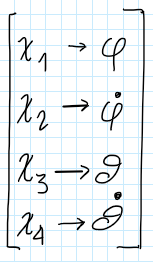

Inoltre, per definire il nostro sistema SIMO in forma matriciale, avremo bisogno del supporto delle matrici A-B-C-D. Per fare questo definiamo queste funzioni di supporto:

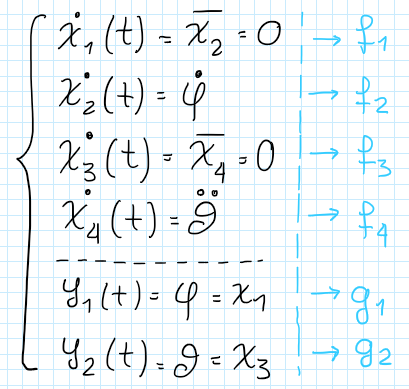

Da qui è quindi possibile poi ricavare le matrici A-B-C-D come segue:

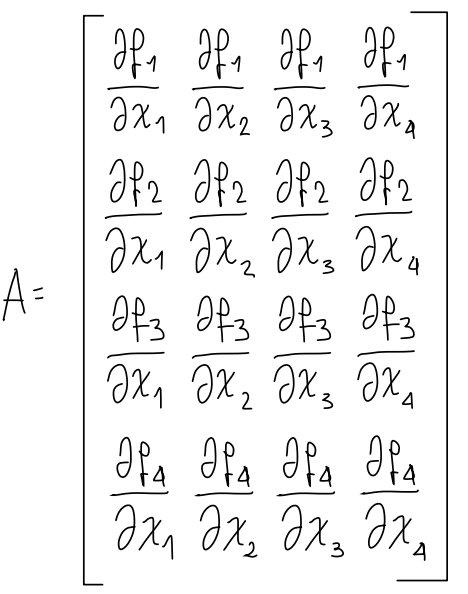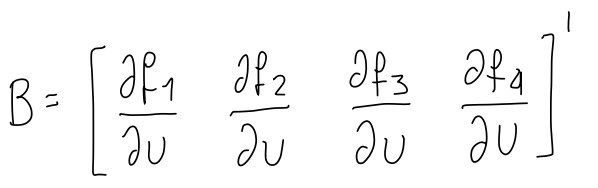

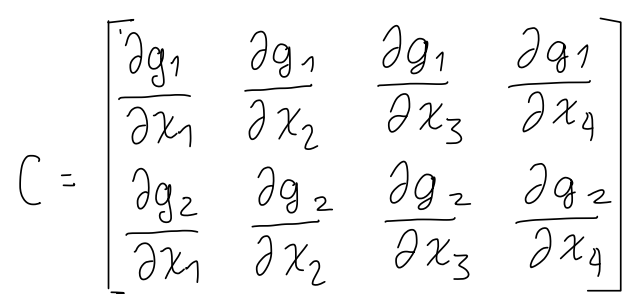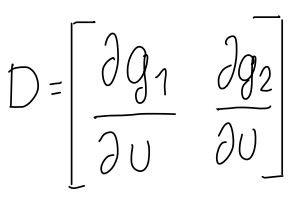

Dove le matrici A e B hanno nello specifico questa forma:

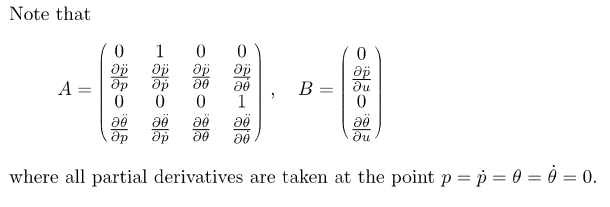

Queste matrici ci permettono di scrivere:


$$\left\lbrack \begin{array}{c}
\phi^{\ldotp } \\
\overset{\ldotp \ldotp }{\phi \;} \\
\overset{\ldotp }{\theta \;} \\
\overset{\ldotp \ldotp }{\theta \;} 
\end{array}\right\rbrack =A\left\lbrack \begin{array}{c}
\phi \\
\phi^{\ldotp } \\
\theta \;\\
\overset{\ldotp }{\theta \;} 
\end{array}\right\rbrack +\textrm{Bu}$$


syms u;
theta2_differenziabile = subs(theta2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u});
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u});

%phi, phi_primo, theta, theta_primo, C_m (u = INPUT)
equilibrio = {0,0,0,0,0};

A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(theta2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A42 = subs(diff(theta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A43 = subs(diff(theta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A44 = subs(diff(theta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A = [A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -4.164 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 11.88 & 0 \end{array}\right)$$


B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B31 = 0;
B41 = subs(diff(theta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B = [B11;B21;B31;B41]

$$B = \left(\begin{array}{c} 0\\ 0.0247\\ 0\\ 0.1253 \end{array}\right)$$


C = [0,0,1,0] % Riportiamo in uscita solamente l'angolo

C =      0     0     1     0


%C = eye(4); % Riportiamo in uscita tutte le variabili di stato
D = 0

D = 0


syms s G(s);
G = collect(simplify(C*(s*eye(4)-A)^(-1)*B+D))

$$G = \frac{5013.0}{40000.0\,s^{2}-4.754e+5}$$

## Analisi stabilità

Studio dell'asintotica stabilità tramite gli autovalori della matrice A: come noto dalla teoria, il sistema è asintoticamente stabile se gli autovalori hanno tutti parte reale negativa; è instabile invece se è presente almeno un autovalore con parte reale strettamente positiva.

lambda = eig(A)

$$lambda = \left(\begin{array}{c} 3.447\\ 0\\ 0\\ -3.447 \end{array}\right)$$

Si vede come il sistema, in anello aperto, non sia asintoticamente stabile (come previsto).

Lo stato del sistema, nel nostro caso, risulta essere accessibile, poichè sono misurazioni che possono essere direttamente realizzate per mezzo di tecniche di sensor fusion.

Per ora vogliamo controllare solamente l'angolo $\theta \;$, e quindi ci poniamo in una condizione di sistema SISO (input la coppia motrice, output l'accelerazione theta_2_p):


$${\left\{\begin{array}{c}
x\left(t\right)=Ax{\left(t\right)}+Bu\left(t\right)\\
y{\left(t\right)}=Cx{\left(t\right)}+Du\left(t\right)
\end{array}\right)}$$


Utilizzando la legge di controllo


$$u{\left(t\right)}=-Kx{\left(t\right)}+w{\left(t\right)}$$


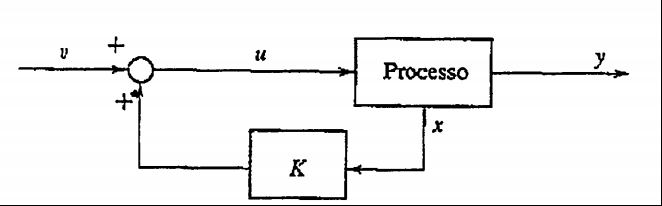

Per la scelta della matrice K


$$x{\left(t\right)}=Ax{\left(t\right)}+Bu{\left(t\right)}=Ax{\left(t\right)}+B{\left(-Kx{\left(t\right)}+w{\left(t\right)}\right)}\to legge\ di\ controllo\ in\ anello\ chiuso$$



$$=Ax{\left(t\right)}-BKx{\left(t\right)}+Bw\left(t\right)={\left(A-BK\right)}x{\left(t\right)}+Bw{\left(t\right)}$$



$$A_{cl} =A-BK=matrice\;di\;stato\;in\;closed-loop$$


Devo esprimere A e B in forma canonica di raggiungibilità:

% Passing from symbolic to real values
A_real = double(A)

A_real =          0    1.0000         0         0
         0         0   -4.1645         0
         0         0         0    1.0000
         0         0   11.8849         0


B_real = double(B);
C_real = double(C);
D_real = double(D);

[num, den] = numden(G)

$$num = 25.07$$

$$den = 200.0\,s^{2}-2377.0$$

coeffs_num = double(coeffs(num,'all'));
coeffs_den = double(coeffs(den,'all'));

%% TODO: see http://www.ladispe.polito.it/corsi/contrautoinf270/material/IntroduzioneMatlab1.pdf
sys_1 = tf(coeffs_num, coeffs_den)


sys_1 =
 
      25.07
  --------------
  200 s^2 - 2377
 
Continuous-time transfer function.



T = 0:0.01:5;
U = sin(T);
[YS,TS,XS] = lsim(sys_1,U,T) 

YS = 	1.0e+04 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


TS =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



XS =

     []



figure(1),plot(TS,XS)

Error using plot
Vectors must be the same length.

figure(2),plot(TS,YS)
ltiview

sys = ss(A_real,B_real,C_real,D_real)

poli=roots(poly(A_real))

M_r=ctrb(A_real,B_real) % Matrice di raggiungibilità
rank(M_r) % Rango è pieno quindi il sistema è completamente raggiungibile


%%% TODO
T_alpha=Calcola_T_alpha(A_real) % Matrice T_alpha
Tc=Rpiu*T_alpha; % Tc della forma canonica di controllo
Ac=Tc\A_real*Tc % Matrice di sistema
Bc=Tc\B_real % Matrice degli ingressi
Cc=C*Tc % Matrice delle uscite
SysC=ss(Ac,Bc,Cc,0); % SysC = sistema in forma canonica di controllo
roots(poly(Ac)) % Autovalori della matrice Ac

%%% TODO: place eigenvalues

%%% TODO: root locus